classification_res = readtable("Classification_raw_results.csv");
classification_res{:, "Level"} = erase(classification_res{:, "Level"}, 'Level ');
classification_res.Level = str2double(classification_res.Level);


base_res = readtable("Classification_base_results_final_big.csv");
base_res{:, "Level"} = erase(base_res{:, "Level"}, 'Level ');
base_res.Level = str2double(base_res.Level);


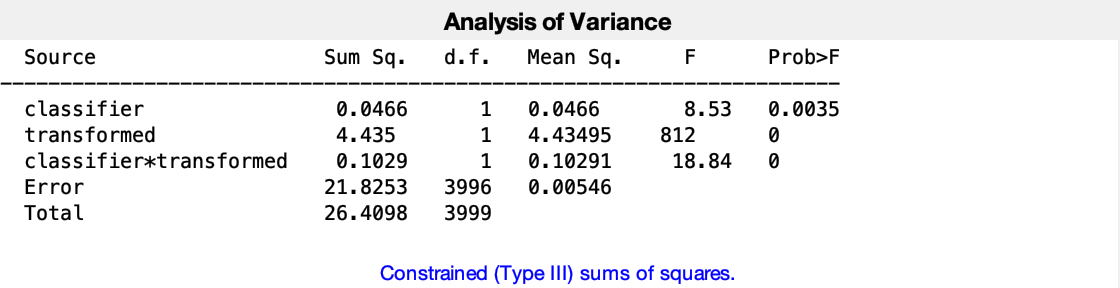

classification_res.Transformed(:,1) = "Yes";
base_res.Transformed(:,1) = "No";
combined_res = [classification_res; base_res];
[p, tmp, statsOut] = anovan(combined_res.Accuracy, {combined_res.Classifier, combined_res.Transformed}, 'model', 'interaction', 'varnames', {'classifier', 'transformed'});

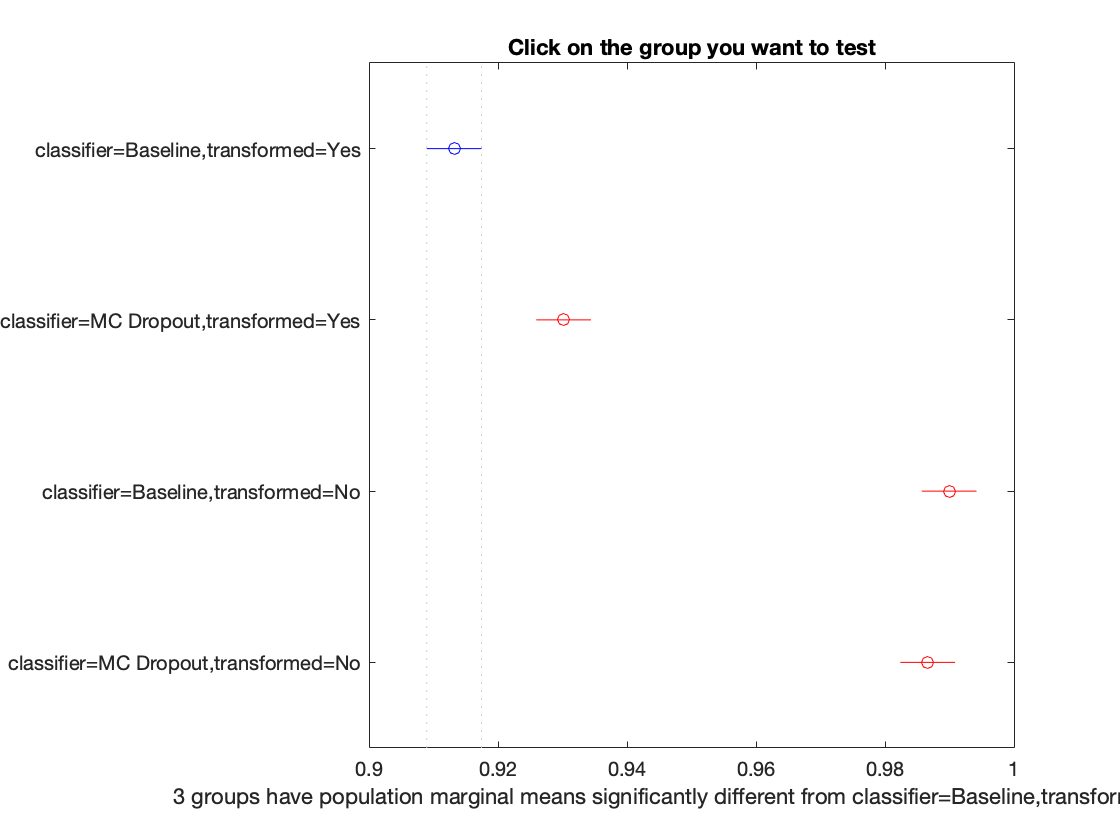

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0287   -0.0170   -0.0053    0.0011
    1.0000    3.0000   -0.1139   -0.0759   -0.0379    0.0000
    1.0000    4.0000   -0.1114   -0.0734   -0.0354    0.0000
    2.0000    3.0000   -0.0969   -0.0590   -0.0210    0.0004
    2.0000    4.0000   -0.0944   -0.0564   -0.0184    0.0008
    3.0000    4.0000   -0.0499    0.0025    0.0549    0.9993


[p, tmp, statsOut] = anovan(combined_res.ROC, {combined_res.Classifier, combined_res.Transformed}, 'model', 'interaction', 'varnames', {'classifier', 'transformed'});

Unable to resolve the name combined_res.ROC.

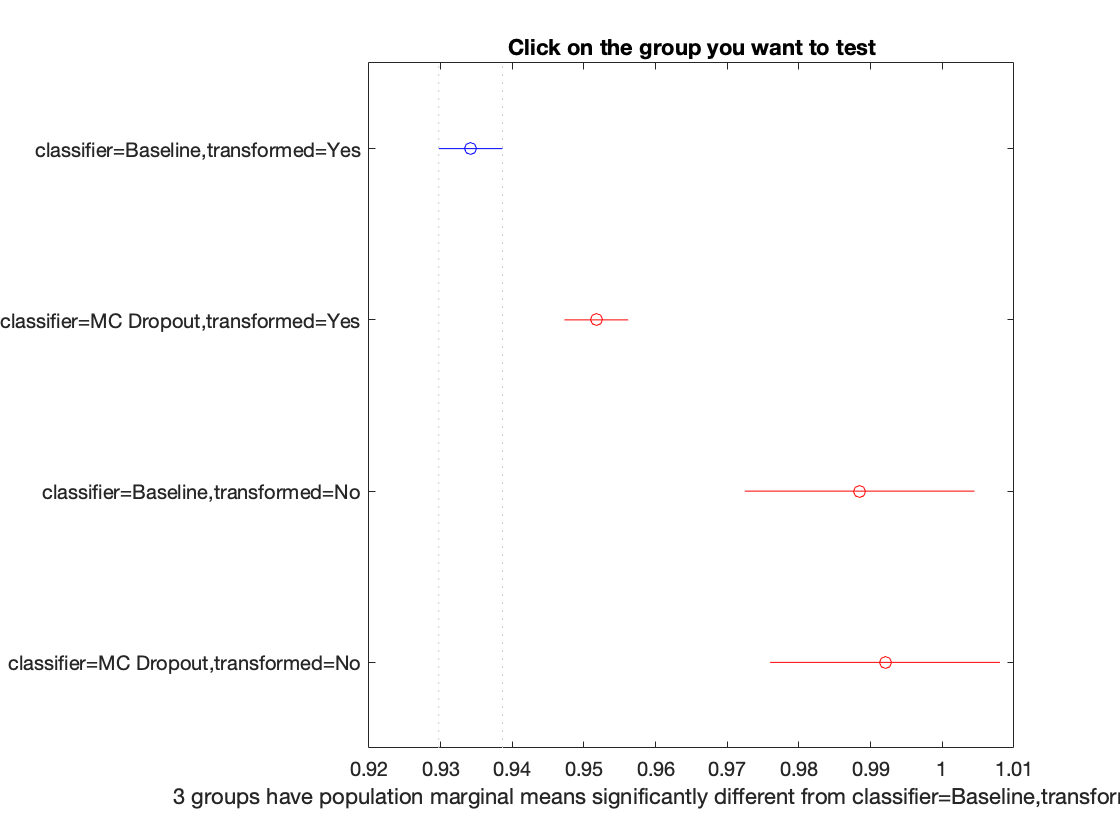

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0242   -0.0175   -0.0109    0.0000
    1.0000    3.0000   -0.0759   -0.0543   -0.0327    0.0000
    1.0000    4.0000   -0.0794   -0.0578   -0.0362    0.0000
    2.0000    3.0000   -0.0583   -0.0367   -0.0151    0.0001
    2.0000    4.0000   -0.0619   -0.0403   -0.0187    0.0000
    3.0000    4.0000   -0.0334   -0.0036    0.0263    0.9900


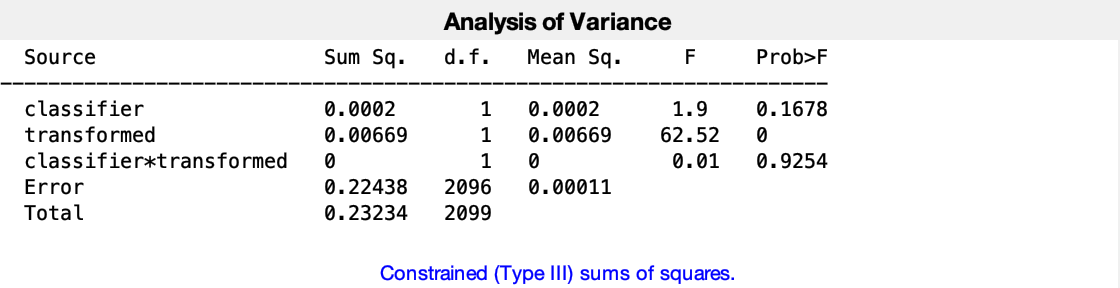

[p, tmp, statsOut] = anovan(combined_res.Brier, {combined_res.Classifier, combined_res.Transformed}, 'model', 'interaction', 'varnames', {'classifier', 'transformed'});

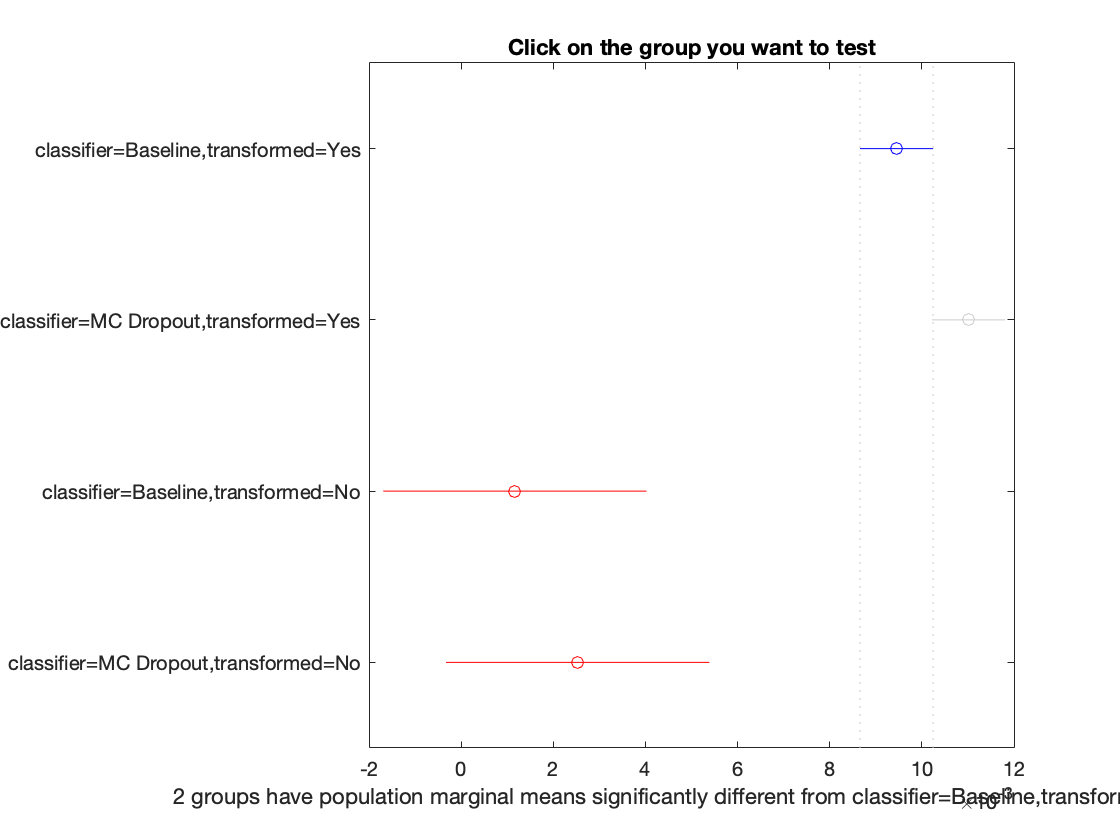

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0028   -0.0016   -0.0004    0.0041
    1.0000    3.0000    0.0044    0.0083    0.0121    0.0000
    1.0000    4.0000    0.0031    0.0069    0.0108    0.0000
    2.0000    3.0000    0.0060    0.0098    0.0137    0.0000
    2.0000    4.0000    0.0046    0.0085    0.0123    0.0000
    3.0000    4.0000   -0.0067   -0.0014    0.0040    0.9124



%grpstats(combined_res, {'Classifier', 'Transformed'}, 'mean', 'DataVars', "Accuracy")

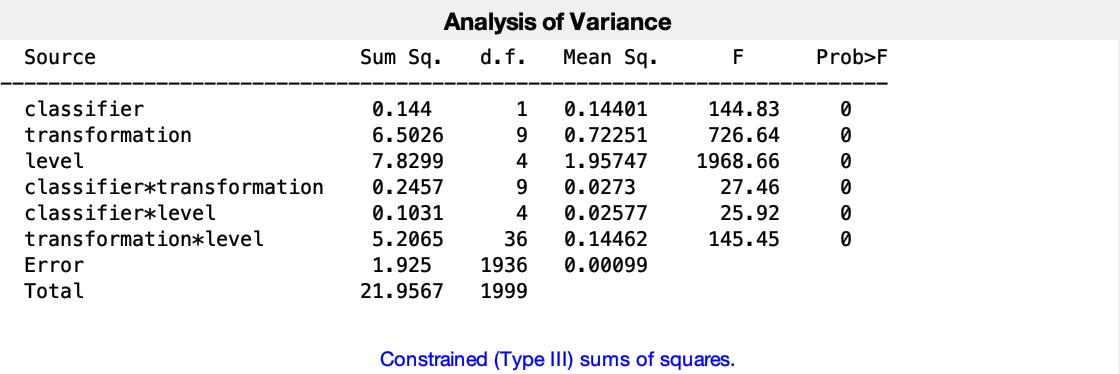


% ANOVA for acc
[p, tmp, statsOut] = anovan(classification_res.Accuracy, {classification_res.Classifier, classification_res.Transformation, classification_res.Level}, 'model', 'interaction', 'varnames', {'classifier', 'transformation', 'level'});%, 'continuous', [3]);

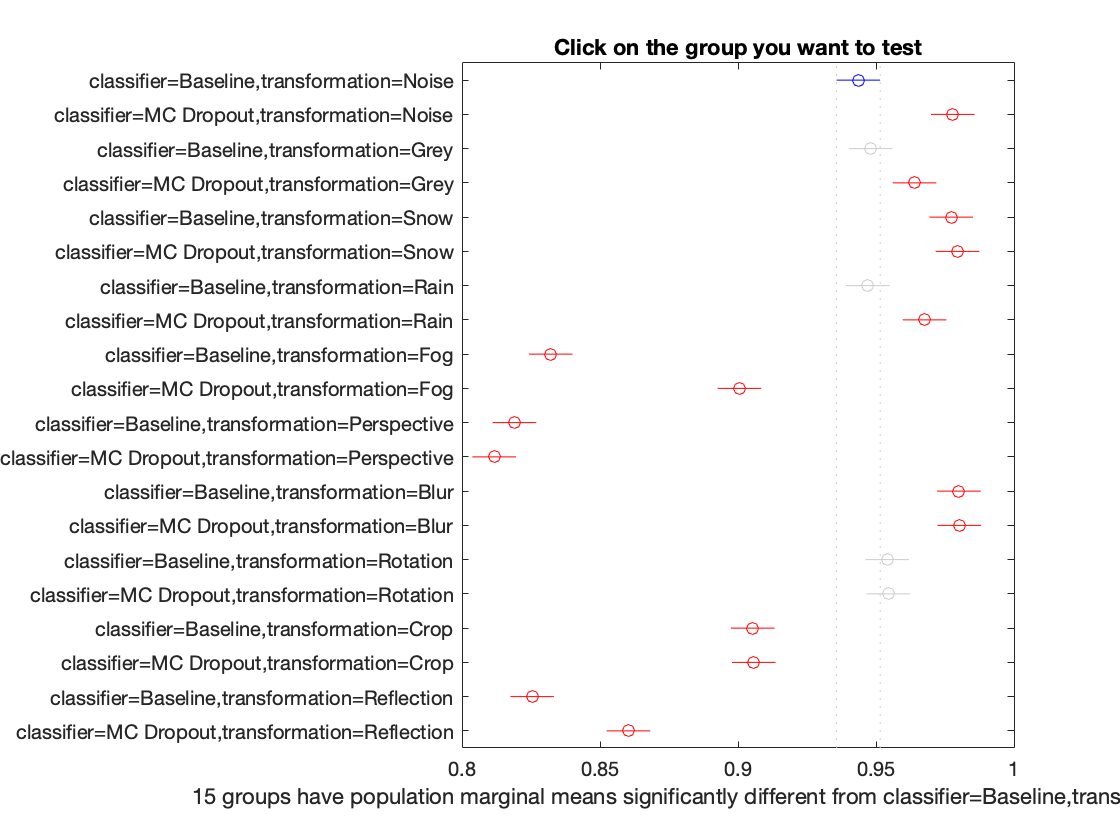

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0500   -0.0342   -0.0184    0.0000
    1.0000    3.0000   -0.0203   -0.0045    0.0113    1.0000
    1.0000    4.0000   -0.0362   -0.0204   -0.0046    0.0009
    1.0000    5.0000   -0.0494   -0.0336   -0.0178    0.0000
    1.0000    6.0000   -0.0517   -0.0359   -0.0201    0.0000
    1.0000    7.0000   -0.0192   -0.0034    0.0124    1.0000
    1.0000    8.0000   -0.0398   -0.0240   -0.0082    0.0000
    1.0000    9.0000    0.0957    0.1115    0.1273    0.0000
    1.0000   10.0000    0.0273    0.0431    0.0589    0.0000
    1.0000   11.0000    0.1088    0.1246    0.1404    0.0000


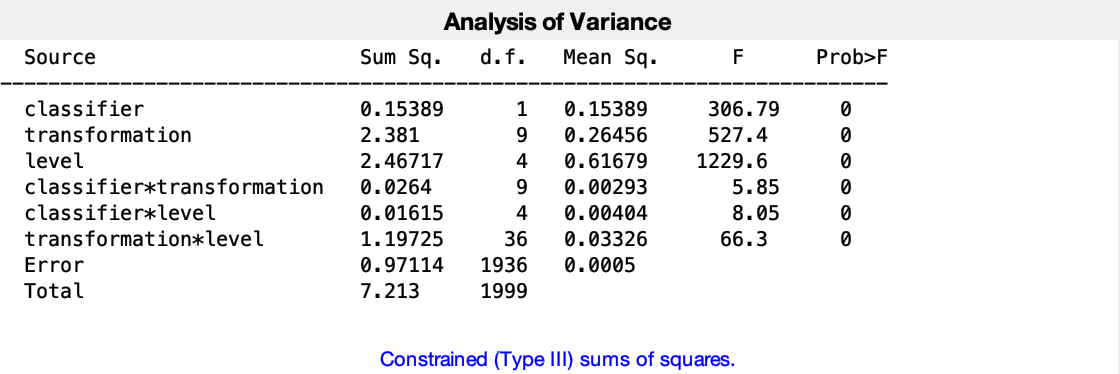


%AUROC ANALYSIS
[p, tmp, statsOut] = anovan(classification_res.ROC, {classification_res.Classifier, classification_res.Transformation, classification_res.Level}, 'model', 'interaction', 'varnames', {'classifier', 'transformation', 'level'});%, 'continuous', [3]);

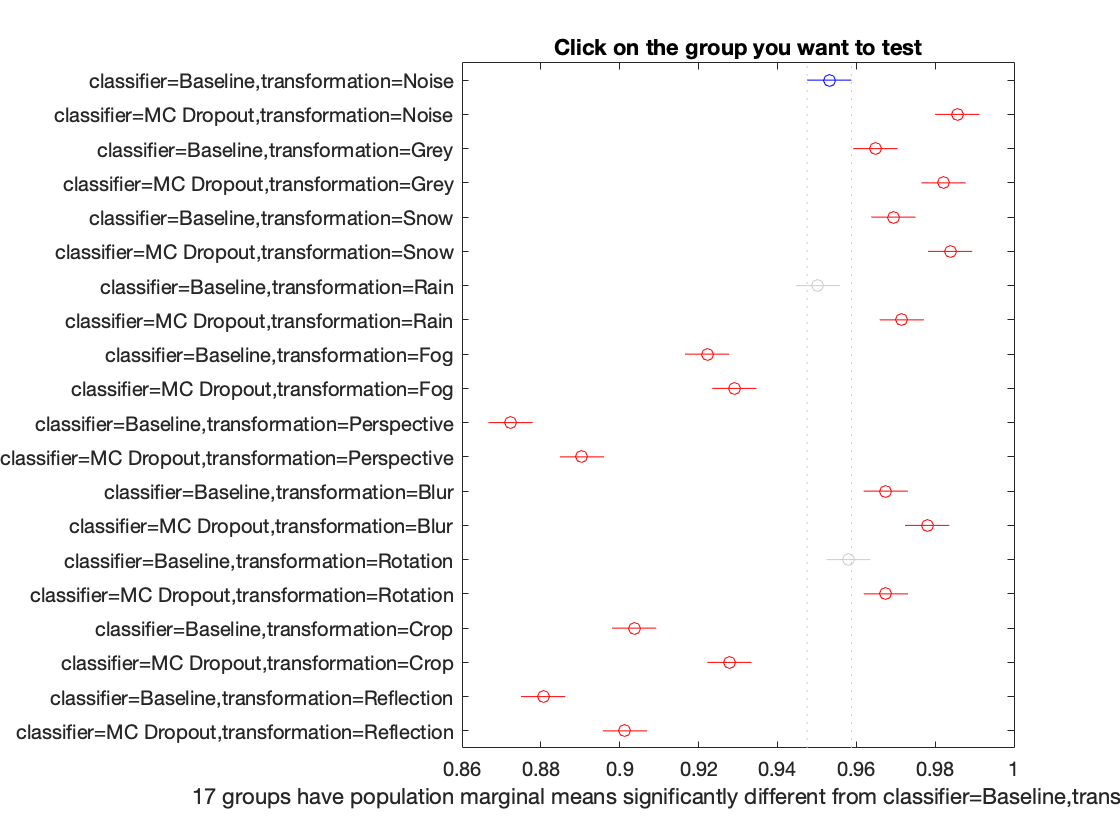

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0437   -0.0325   -0.0212    0.0000
    1.0000    3.0000   -0.0229   -0.0117   -0.0005    0.0298
    1.0000    4.0000   -0.0402   -0.0290   -0.0178    0.0000
    1.0000    5.0000   -0.0275   -0.0163   -0.0050    0.0001
    1.0000    6.0000   -0.0419   -0.0307   -0.0194    0.0000
    1.0000    7.0000   -0.0084    0.0029    0.0141    1.0000
    1.0000    8.0000   -0.0297   -0.0184   -0.0072    0.0000
    1.0000    9.0000    0.0198    0.0310    0.0422    0.0000
    1.0000   10.0000    0.0128    0.0241    0.0353    0.0000
    1.0000   11.0000    0.0696    0.0809    0.0921    0.0000


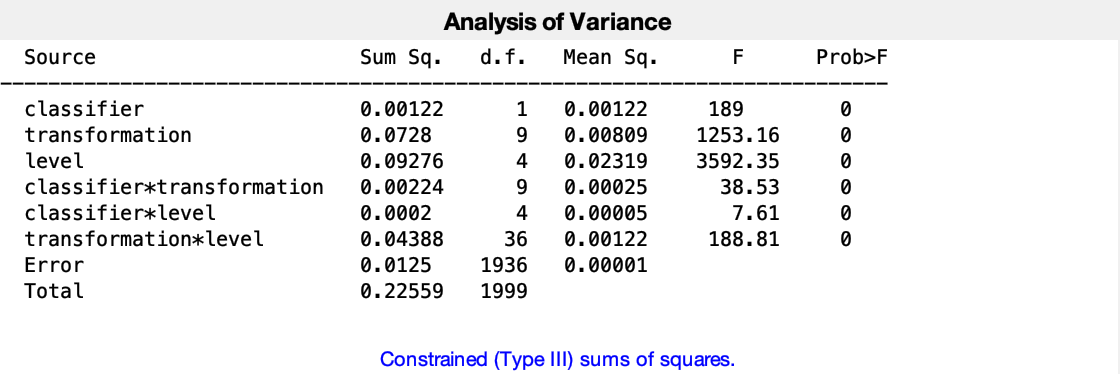


%Brier analysis
[p, tmp, statsOut] = anovan(classification_res.Brier, {classification_res.Classifier, classification_res.Transformation, classification_res.Level}, 'model', 'interaction', 'varnames', {'classifier', 'transformation', 'level'});%, 'continuous', [3]);

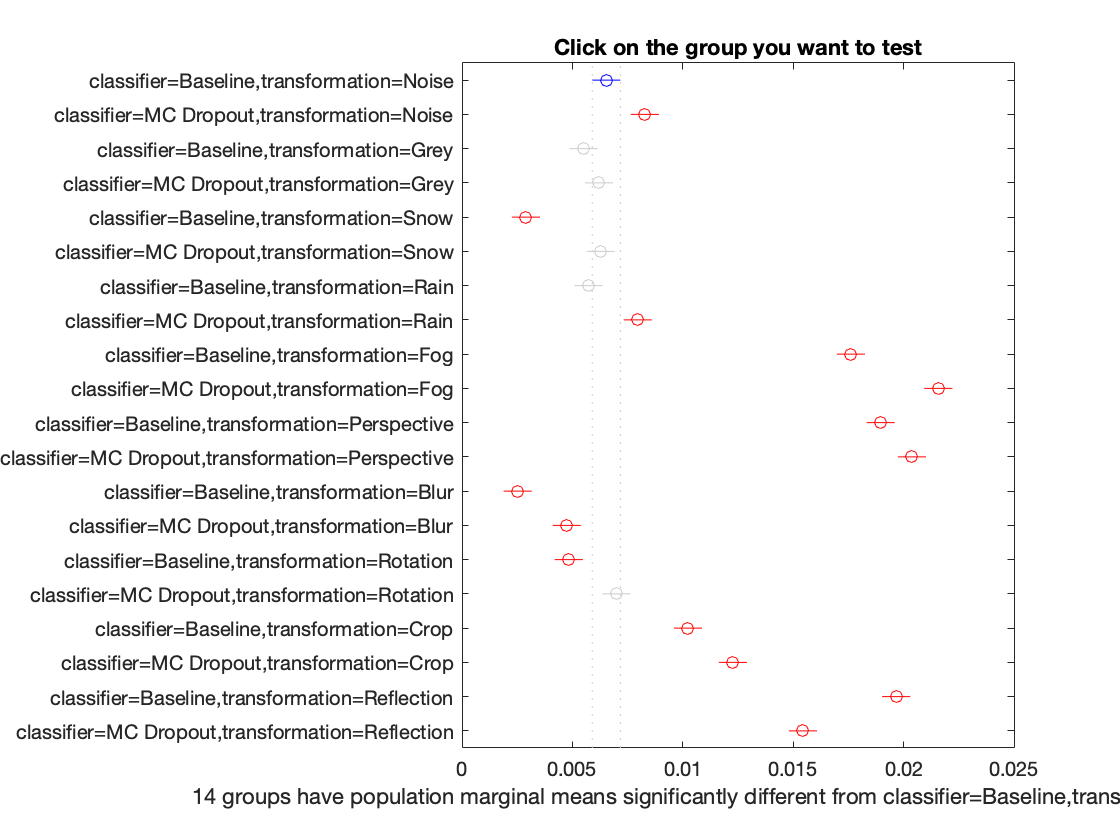

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);


results_acc

results_acc =     1.0000    2.0000   -0.0030   -0.0017   -0.0005    0.0002
    1.0000    3.0000   -0.0003    0.0010    0.0023    0.3236
    1.0000    4.0000   -0.0009    0.0003    0.0016    1.0000
    1.0000    5.0000    0.0024    0.0036    0.0049    0.0000
    1.0000    6.0000   -0.0010    0.0003    0.0015    1.0000
    1.0000    7.0000   -0.0005    0.0008    0.0021    0.7628
    1.0000    8.0000   -0.0027   -0.0014   -0.0002    0.0109
    1.0000    9.0000   -0.0124   -0.0111   -0.0098    0.0000
    1.0000   10.0000   -0.0163   -0.0150   -0.0138    0.0000
    1.0000   11.0000   -0.0137   -0.0124   -0.0112    0.0000


%OOD PART
ood_res_base = readtable("Ood_results_raw_final.csv");
ood_res_transform = readtable("Ood_results_transform_raw_final.csv");


ood_combined = [ood_res_base; ood_res_transform];

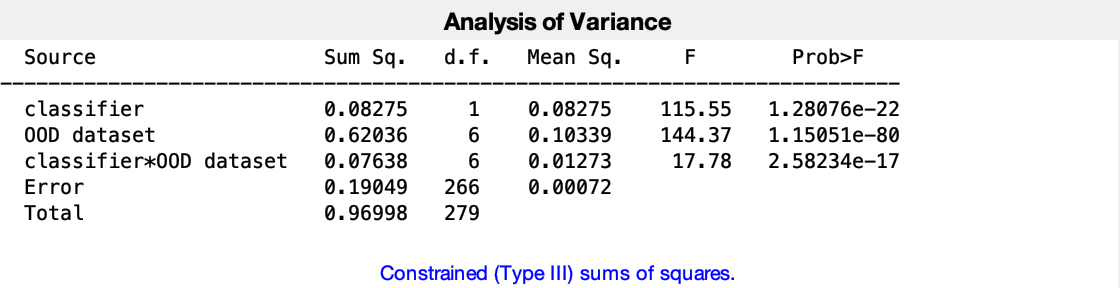

[p, tmp, statsOut] = anovan(ood_res_base.ROC, {ood_res_base.Classifier, ood_res_base.Measure}, 'model', 'interaction', 'varnames', {'classifier', 'OOD dataset'});

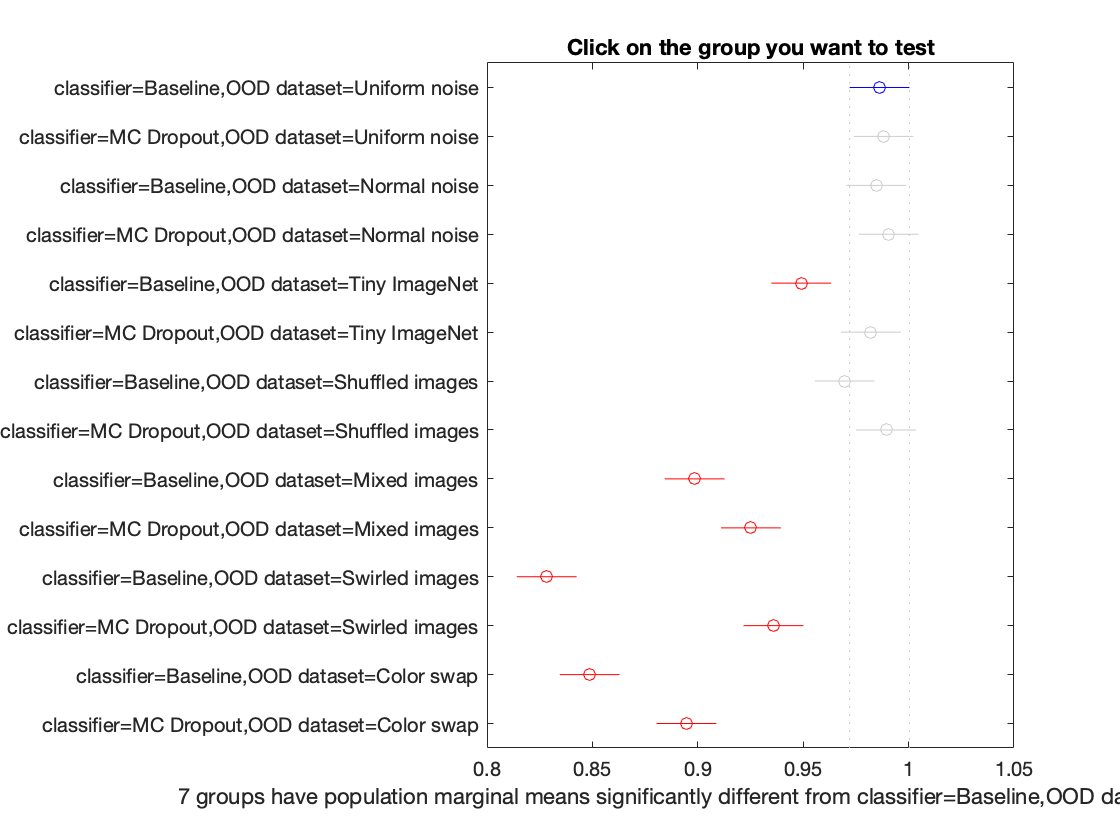

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.0302   -0.0018    0.0265    1.0000
    1.0000    3.0000   -0.0268    0.0016    0.0300    1.0000
    1.0000    4.0000   -0.0327   -0.0043    0.0240    1.0000
    1.0000    5.0000    0.0088    0.0372    0.0655    0.0009
    1.0000    6.0000   -0.0243    0.0041    0.0325    1.0000
    1.0000    7.0000   -0.0118    0.0166    0.0449    0.7952
    1.0000    8.0000   -0.0315   -0.0031    0.0253    1.0000
    1.0000    9.0000    0.0593    0.0877    0.1160    0.0000
    1.0000   10.0000    0.0326    0.0610    0.0894    0.0000
    1.0000   11.0000    0.1295    0.1579    0.1863    0.0000


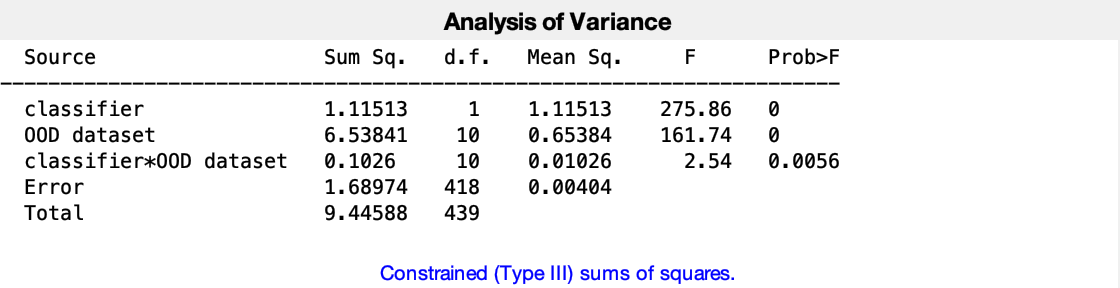

[p, tmp, statsOut] = anovan(ood_res_transform.ROC, {ood_res_transform.Classifier, ood_res_transform.Measure}, 'model', 'interaction', 'varnames', {'classifier', 'OOD dataset'});

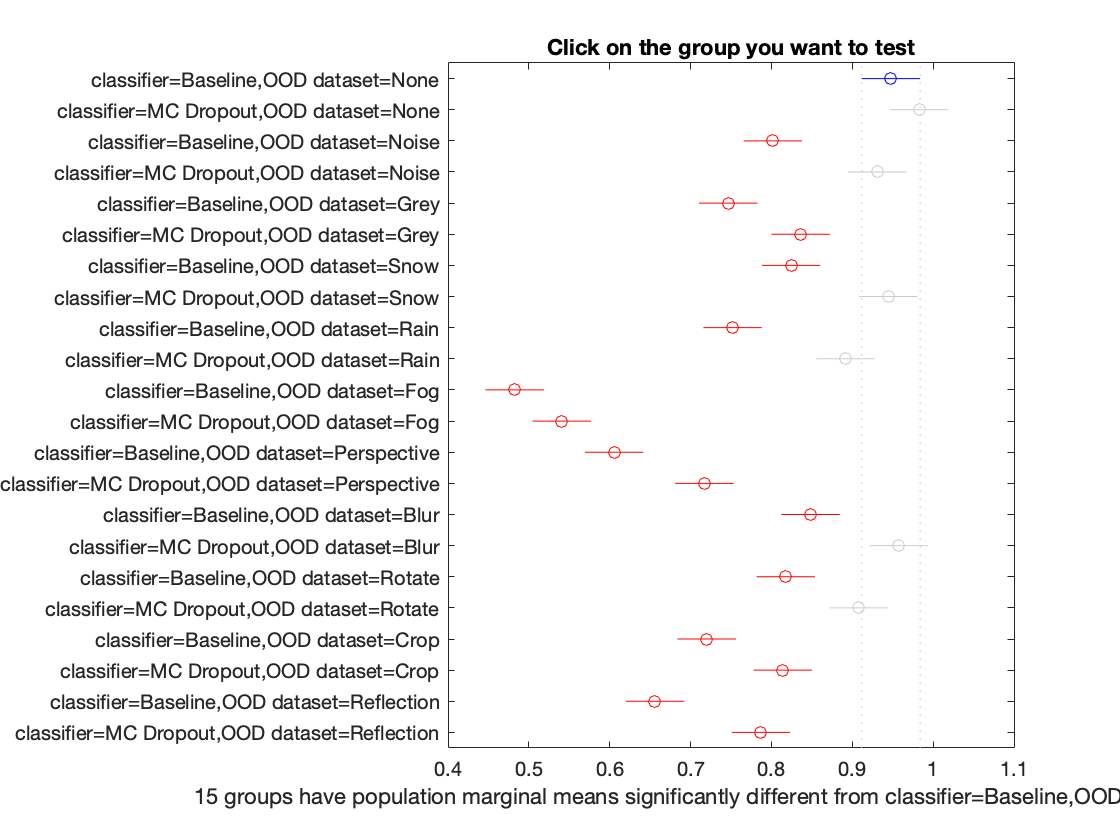

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.1071   -0.0349    0.0373    0.9837
    1.0000    3.0000    0.0738    0.1460    0.2183    0.0000
    1.0000    4.0000   -0.0556    0.0166    0.0888    1.0000
    1.0000    5.0000    0.1290    0.2012    0.2735    0.0000
    1.0000    6.0000    0.0394    0.1116    0.1839    0.0000
    1.0000    7.0000    0.0513    0.1235    0.1958    0.0000
    1.0000    8.0000   -0.0688    0.0035    0.0757    1.0000
    1.0000    9.0000    0.1237    0.1959    0.2682    0.0000
    1.0000   10.0000   -0.0160    0.0562    0.1285    0.3992
    1.0000   11.0000    0.3930    0.4653    0.5375    0.0000


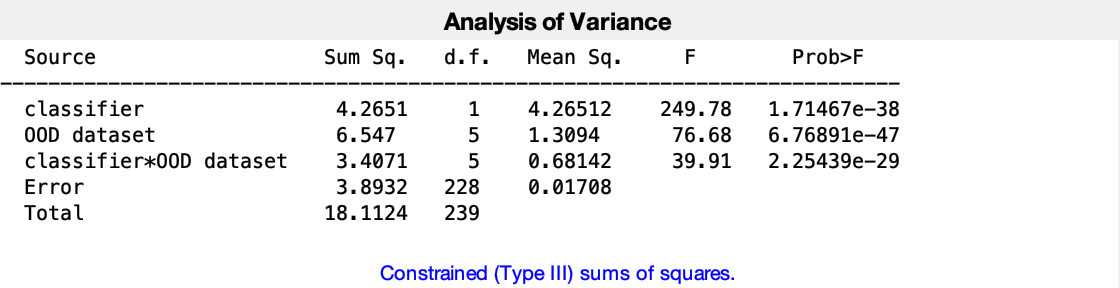

ood_res_gan = readtable("Ood_results_gan_combined_min.csv");
[p, tmp, statsOut] = anovan(ood_res_gan.ROC, {ood_res_base.Classifier, ood_res_base.GAN}, 'model', 'interaction', 'varnames', {'classifier', 'OOD dataset'});

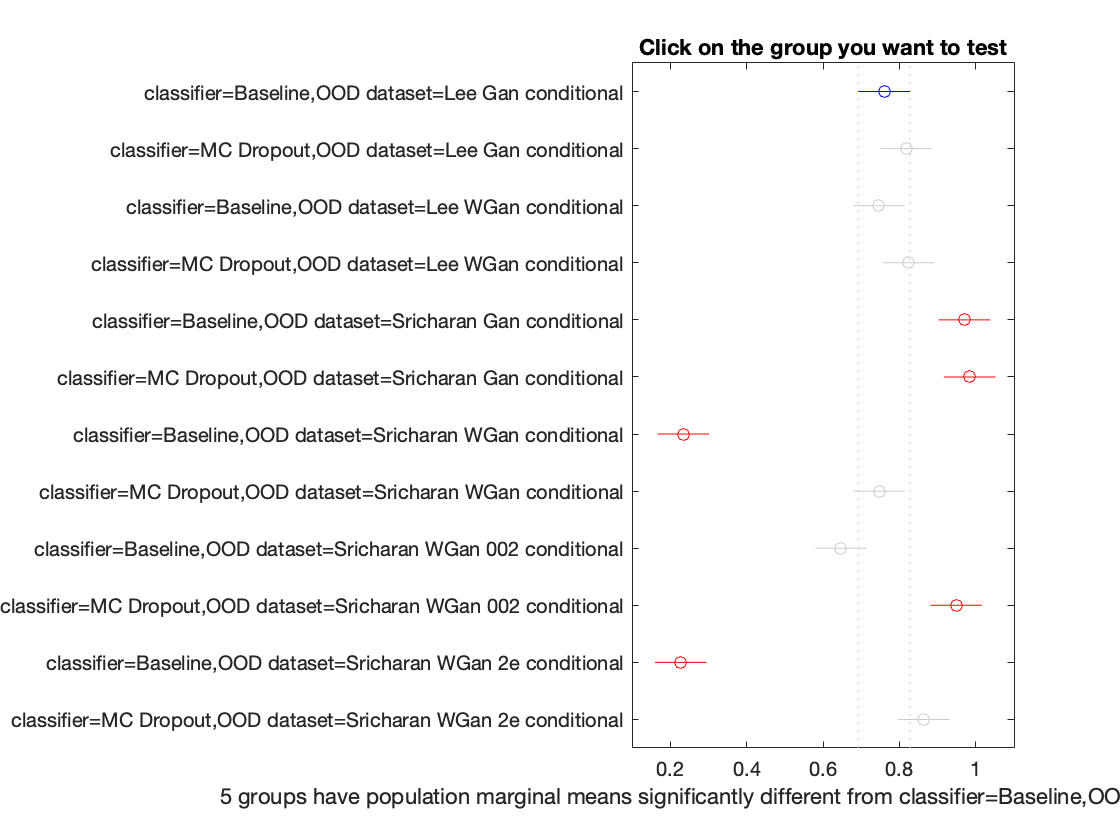

figure; results_acc = multcompare(statsOut, 'Dimension', [1 2]);

results_acc

results_acc =     1.0000    2.0000   -0.1926   -0.0575    0.0775    0.9653
    1.0000    3.0000   -0.1211    0.0140    0.1490    1.0000
    1.0000    4.0000   -0.1999   -0.0648    0.0702    0.9204
    1.0000    5.0000   -0.3452   -0.2101   -0.0751    0.0000
    1.0000    6.0000   -0.3588   -0.2238   -0.0887    0.0000
    1.0000    7.0000    0.3911    0.5261    0.6612    0.0000
    1.0000    8.0000   -0.1216    0.0134    0.1484    1.0000
    1.0000    9.0000   -0.0218    0.1132    0.2483    0.2066
    1.0000   10.0000   -0.3235   -0.1885   -0.0535    0.0003
    1.0000   11.0000    0.3973    0.5323    0.6674    0.0000
